# Assignment 3 in Optreg

#### **By Alexander Brevad Rambech**

### **Problem 1**

For the LP problem on the standard form:

- 
$$\min_x c^Tx ~ \text{ s.t } ~ Ax=b, ~ x \geq 0,$$


where $c, x \in I\!R^n
$ and $b \in I\!R^m$. The KKT-conditions are given by:

- 
$$A^T\lambda^* + s^* = c$$


- 
$$Ax^* = b$$


- 
$$x^* \geq 0$$


- 
$$s^* \geq 0$$


- 
$$s^*_ix_i^* = 0, ~ i = 1, \dots, n$$


**a)**

The ***Newton direction*** is given by $p_k^N = -(\nabla^2f_k)^{-1} \nabla f_k$, for this to hold our objective function$f_k = c^Tx$ must be adecuatly smooth. Since $\nabla^2 f_k = 0$ we cannot define a Newton direction.

**b)**

From the definition of convex functions we have that, a function is convex if it's domain $S$ is convex and there exists two arbitrary points $x
$ and $y$ such that you can draw a straight line between them and still  be within the set. 

Since all LPs have linear constraints, they form polyhedreons, which are convex sets. 

The function $f$ is said to be convex if the following property holds:

- 
$$f(\alpha x + (1-\alpha)y) \leq \alpha f(x) +(1-\alpha) f(y), ~ \forall  \alpha \in [0, 1]$$


Checking for this property in out objective function, we have that:

- 
$$\alpha f(x) + (1-\alpha) f(x) = c^Tx + (1- \alpha) c^Ty = \alpha c^Tx + c^Ty - \alpha c^Ty$$


- 
$$f(\alpha x + (1- \alpha)y) = c^T(\alpha x + (1-\alpha) y) = \alpha c^Tx + c^Ty- \alpha c^Ty $$


The two terms are equal and convexity holds for the function $f$.

From the definition of the convex optimization problem it follows that a the problem is convex if 

- the objective function is convex

- the equality constraint functions $c_1(\cdot), ~ i \in \mathcal{E}$, are linear, and

- the inequality constraint functions $c_i(\cdot), ~i \in \mathcal{I}$, are concave.

All these hold for out problem, and generally do for all LP problems.

**c)**

In order to find the KKT-conditions of the dual problem we change it from a maximization problem to a minimization problem, this yields the problem $\min_{\lambda} - b^T \lambda, ~ s.t ~ c- A^T\lambda \geq 0$. The lagrangian for this problem is given by:

- 
$$\bar{\mathcal{L}}(\lambda,x) = -b^T\lambda -x^T(c-A^T\lambda) $$


We find the first KKT-condition of the problem using $\nabla_\lambda \bar{\mathcal{L}}(\lambda^*, x^*) = 0$, this gives:

- 
$$\nabla_\lambda \bar{\mathcal{L}}(\lambda^*, x^*) = - b + (x^T A^T)^T = Ax - b = 0$$


The rest of the KKT-conditions are then as follows:

- $Ax^*=b$,

- $A^T\lambda^* \leq c$,

- 
$$x^* \geq 0$$


- 
$$(c-A^T \lambda^*)_i \cdot x_i^* = 0, ~ i = 1, \dots, n$$


If we introduce the slack variable $s$ defined as $s = (c - A^T\lambda)$, the KKT-conditions of the dual problem matches those of the primal problem.

**d)**

Since they have the same KKT-conditions, they also have the same values, giving the relation $c^Tx^*=b^T\lambda^*$

**e)**

A point $x'$ is a basic feasible point if it is part of the feasible set $\Omega$ and $\exists$ a subset $\mathcal{B} \in \mathcal{I} \cap \mathcal{E}$ such that:

- $\mathcal{B}$ contains exactly $m$ indices,

- $i \notin \mathcal{B} \rightarrow x_i = 0$,

- The $m \times m$ matrix $B$ is defined by $B = [A_i]_{i \in \mathcal{B}}$ is nonsingular.

**f) **

Since $A$ is always full row rank, this means that the constraints are linearly independent to one another, it is therefore implied that the gradient of the constraints $\nabla c_i (x)$ are so as well, meaning they are LICQ.

### Problem 2

**a)**

The problem stated in the task can be represented by the following equations:

**b)**

Here I've used the contour plotting from the fig_prob2.m file that was attached to this assignment with some very minor changes.

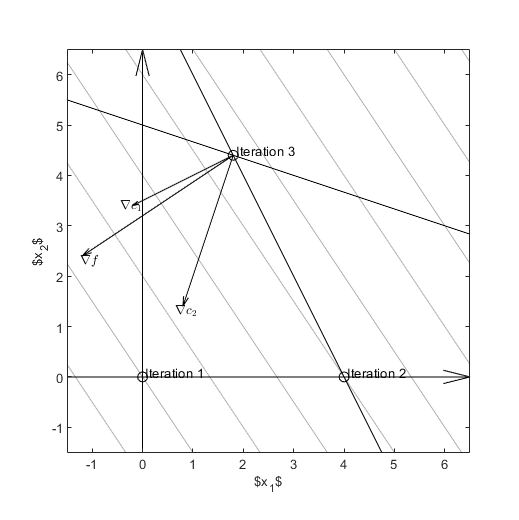

% fig_prob

x1_l = -1.5; x1_h = 6.5;
x2_l = -1.5; x2_h = 6.5;
res = 0.1;

[x1, x2] = meshgrid(x1_l:res:x2_h, x1_l:res:x2_h);

f = -(3/2)*x1 - x2;

levels = (-32:2:6)';

fig = figure(1);
% Set fontsize for the labels and lengend
fontsize = 8;
% Set the figure dimension units to centimeters
set(gcf, 'units','centimeters');
% Figure paper dimensions:
w = 11; % 9 cm wide
h = 11; % 9 cm tall
% Set the dimensions of the figure
pos = get(gcf, 'position');
set(gcf, 'position', [pos(1), pos(2), w, h]);

[C, h] = contour(x1, x2, f, levels, 'Color', .7*[1 1 1]);
% set(h, 'ShowText','on', 'LabelSpacing',500);
hold('on');
grid('off');
axis('square');

% plot([0 0], [x1_l, x1_h], 'k');
% plot([x2_l, x2_h], [0 0], 'k');

% plot_arrow(0,x1_l,0,x1_h);
point1_arrow = [0,x1_l];
point2_arrow1 = [0,x1_h];
d_point = point2_arrow1-point1_arrow;
quiver(point1_arrow(1), point1_arrow(2), d_point(1), d_point(2), 0, 'black')

% plot_arrow(x2_l,0,x2_h,0);
point1_arrow = [x2_l,0];
point2_arrow1 = [x2_h,0];
d_point = point2_arrow1-point1_arrow;
quiver(point1_arrow(1), point1_arrow(2), d_point(1), d_point(2), 0, 'black')


% Plot c_1 and c_2
x_1 = [-10,10];
x_2 = 8 - 2*x_1;
plot(x_1, x_2, 'k');
x_2 = (1/3)*(15 - x_1);
plot(x_1, x_2, 'k');

x1_opt = 1.8;
x2_opt = 4.4;
plot(x1_opt, x2_opt, 'ok');
it1_x1 = 0;
it1_x2 = 0;
plot(it1_x1, it1_x2, 'ok');
it2_x1 = 4;
it2_x2 = 0;
plot(it2_x1, it2_x2, 'ok');

c1_x1 = -2;
c1_x2 = -1;

c2_x1 = -1;
c2_x2 = -3;

f_x1 = -3;
f_x2 = -2;

% plot_arrow(x1_opt,x2_opt, x1_opt+c1_x1,x2_opt+c1_x2, 'linewidth', 2);
point1_arrow = [x1_opt,x2_opt];
point2_arrow1 = [x1_opt+c1_x1,x2_opt+c1_x2];
d_point = point2_arrow1-point1_arrow;
quiver(point1_arrow(1), point1_arrow(2), d_point(1), d_point(2), 0, 'black')

% plot_arrow(x1_opt,x2_opt, x1_opt+c2_x1,x2_opt+c2_x2, 'linewidth', 2);
point1_arrow = [x1_opt,x2_opt];
point2_arrow1 = [ x1_opt+c2_x1,x2_opt+c2_x2];
d_point = point2_arrow1-point1_arrow;
quiver(point1_arrow(1), point1_arrow(2), d_point(1), d_point(2), 0, 'black')

% plot_arrow(x1_opt,x2_opt, x1_opt+f_x1,x2_opt+f_x2, 'linewidth', 2);
point1_arrow = [x1_opt,x2_opt];
point2_arrow1 = [ x1_opt+f_x1,x2_opt+f_x2];
d_point = point2_arrow1-point1_arrow;
quiver(point1_arrow(1), point1_arrow(2), d_point(1), d_point(2), 0, 'black')


text_offset = 0.05;
text(x1_opt+c1_x1-5*text_offset,x2_opt+c1_x2+0*text_offset, '$\nabla c_1$', 'fontsize', fontsize,'interpreter','latex')
text(x1_opt+c2_x1-3*text_offset,x2_opt+c2_x2-2*text_offset, '$\nabla c_2$', 'fontsize', fontsize,'interpreter','latex')
text(x1_opt+f_x1-1*text_offset,x2_opt+f_x2-2*text_offset, '$\nabla f$', 'fontsize', fontsize,'interpreter','latex')
text(it1_x1+1*text_offset,it1_x2+2*text_offset, 'Iteration 1', 'fontsize', fontsize)
text(it2_x1+1*text_offset,it2_x2+2*text_offset, 'Iteration 2', 'fontsize', fontsize)
text(x1_opt+1*text_offset,x2_opt+2*text_offset, 'Iteration 3', 'fontsize', fontsize)

xlabel('$x_1$');
ylabel('$x_2$');
% Set the fontsize of all elements
set(gca, 'fontsize', fontsize); % Sets fontsize on legend and numbers on axis
set(get(gca, 'XLabel'), 'fontsize', fontsize); % Sets the fontsize for the xlabel
set(get(gca, 'YLabel'), 'fontsize', fontsize); % Sets the fontsize for the ylabel

set(gca,'XTick',[-1:1:6],'YTick',[-1:1:6])
xlim([-1.5,6.5])
ylim([-1.5,6.5])

hold('off');


% Create the pdf file
% pdfmatlabfrag(gcf, 'fig_prob2.pdf');

**c) **

Here I have modified the simplex_example.m script in order to use the simplex algorithm with the current problem.

%% Simplex implementation
clear all;

% Using the values from LF
c  = [-3; -2; 0; 0];
A = [2 1 1 0;
     1 3 0 1];
b = [8; 15];

% Starting algorithm at the origin
x0 = [0; 0; 8; 15];

[x, fval, iterates] = simplex(c,A,b,x0,'report');

--------------------------------------------------------------------------------
    Iteration number: 1
    Basic index set:    {3, 4}
    Nonbasic index set: {1, 2}
    x_B =    [   8.0000,   15.0000]'
    x_N =    [   0.0000,    0.0000]'
    lambda = [   0.0000,    0.0000]'
    s_N =    [  -3.0000,   -2.0000]'
    x =      [   0.0000,    0.0000,    8.0000,   15.0000]'
    c'x =     0.00000000
    x_1 will enter the basis (q = 1)
    d =      [   2.0000,    1.0000]'
    x_q+ = x_1+ =    4.0000 	(value of entering variable/step length)
    x_3 will leave the basis (p = 1)
    x_B+ =   [   0.0000,   11.0000]' 	(Current basic vector at new point)
    x_N+ =   [   4.0000,    0.0000]' 	(Current nonbasic vector at new point)
--------------------------------------------------------------------------------


--------------------------------------------------------------------------------
    Iteration number: 2
    Basic index set:    {1, 4}
    Nonbasic index set: {3, 2}
    x_B =    [   4.


iter_x1_x2 = iterates(1:2, :);

% Extract iterates as individual vectors (containing x_1 and x_2):
iter_1 = iter_x1_x2(:,1);
iter_2 = iter_x1_x2(:,2);
iter_3 = iter_x1_x2(:,3);

We ran the algorithm in three iterations inspecting three different basic feasible points and an optimal point was found at $x^* = [1.8 ~ 4.4 ~0~0]^T$ with a minimal function value of $f(x^*) = -14.2$.

**d)**

This is allready done in the figure made in **Problem 2 b)**.

**e)**

### Problem 3

**a)**

The active set of an optimization problem is given by:

- 
$$\mathcal{A}(x^*) = \mathcal{E} \cup \{i \in \mathcal{I} | c_i(x^*) = 0 \}$$


Meaning for an inequality-constraint to be active, it has to be identically zero at the optimal solution $x^*
$.

For our problem, we see that the active set is given by:

- 
$$\mathcal{A}(x^*) = \mathcal{E} \cup \{i \in \mathcal{I} | a_i^Tx^* = b_i  \}$$


**b)**

First we find the lagrangian of the problem, which is given by:

- 
$$\mathcal{L}(x, \lambda) = \frac{1}{2}x^TGx + c^Tx - \sum_{i \in\mathcal{E} \cup \mathcal{I}} \lambda_i (a_i^Tx - b_i)$$


The gradient of the lagrangian is given by

- 
$$\nabla_x \mathcal{L}(x^*, \lambda^*) = Gx^*+ c - \sum_{i \in\mathcal{E} \cup \mathcal{I}} \lambda_i a_i^Tx = 0$$


The rest of the KKT-conditions follow:

-  
$$a_i^Tx^* = b_i, ~ i \in \mathcal{E}$$


- 
$$a_i^Tx^* \geq b_i, ~ i \in \mathcal{I}$$


- 
$$\lambda^* \geq 0, ~ i \in \mathcal{I}$$


- 
$$\lambda_i^*(a_i^Tx^*-b_i) = 0, ~ i \in I$$
